I = readimg(20, 8, 25);
imshow(I);

[height, width, ~] = size(I)

I = preprocess(I);
imshow(I);

colors = splitColor(I);

R = colors(:,:,1);

width = size(I,2);

BK = colors(:,:,4);
W = preprocessChannel(colors(:,:,5));

imshowpair(BK,W,'montage');

[centre, radi] = imfindcircles(W,[5,20]);

if (size(centre,1) > 0)
    imagesize = size(I);
    [xx,yy] = ndgrid((1:imagesize(1))-centre(2),(1:imagesize(2))-centre(1));
    mask = uint8((xx.^2 + yy.^2)<(radi^2));
end

imshow(W);

R = colors(:,:,1);

W = colors(:,:,5);

WE = edge(W,'canny');

imshow(WE);

[H,theta,rho] = hough(WE);
% P = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
P = houghpeaks(H,5);
lines = houghlines(WE,theta,rho,P,'FillGap',width/7,'MinLength',width/2.5)

p1 = struct2table(lines).point1
p2 = struct2table(lines).point2

Pch = [p1;p2]

k = convhull(Pch)

X = Pch(k,1)
Y = Pch(k,2)

mask2 = poly2mask(X,Y,size(I,1),size(I,2));

hold off
imshow(mask2);
imshow(W);
imshow(BK);

imshow(R);


newW = mask2 & W & ~BK;

aux = imdilate(newW, ones(int8(width/8)));

imshow(aux);

imshow(aux & ~mask2);

border = aux & ~mask2;

border2 = border & R;

imshowpair(border, border2, 'montage');

bs = sum(sum(border))
bs2 = sum(sum(border2))

I = readimg(37,1,20);

I = preprocess(I);

imshow(I);

colors = splitColor(I);
W = colors(:,:,5);
R = colors(:,:,1);
B = colors(:,:,2);

BK = colors(:,:,4);

maskW = descriptors(W);
maskR = descriptors(R);
maskB = descriptors(B);

imshowpair(maskB,W, 'montage');

BW = maskB & ~W;

imshow(BW);

I = readimg(17,2,1);
I = preprocess(I);
imshow(I)
[mask, colors, took] = maskFinder(I);

imshow(mask)
montage(struct2array(colors))%, "Size", [1, 5]);

took

imshow(cr)

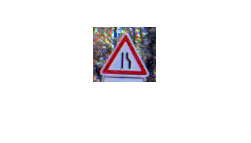

I = readimg(24,3,10);
I = preprocess(I);
figure;
imshow(I)

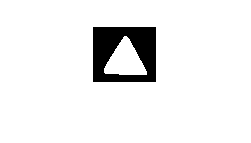

[mask, colors, took] = maskFinder(I);

imshow(mask)

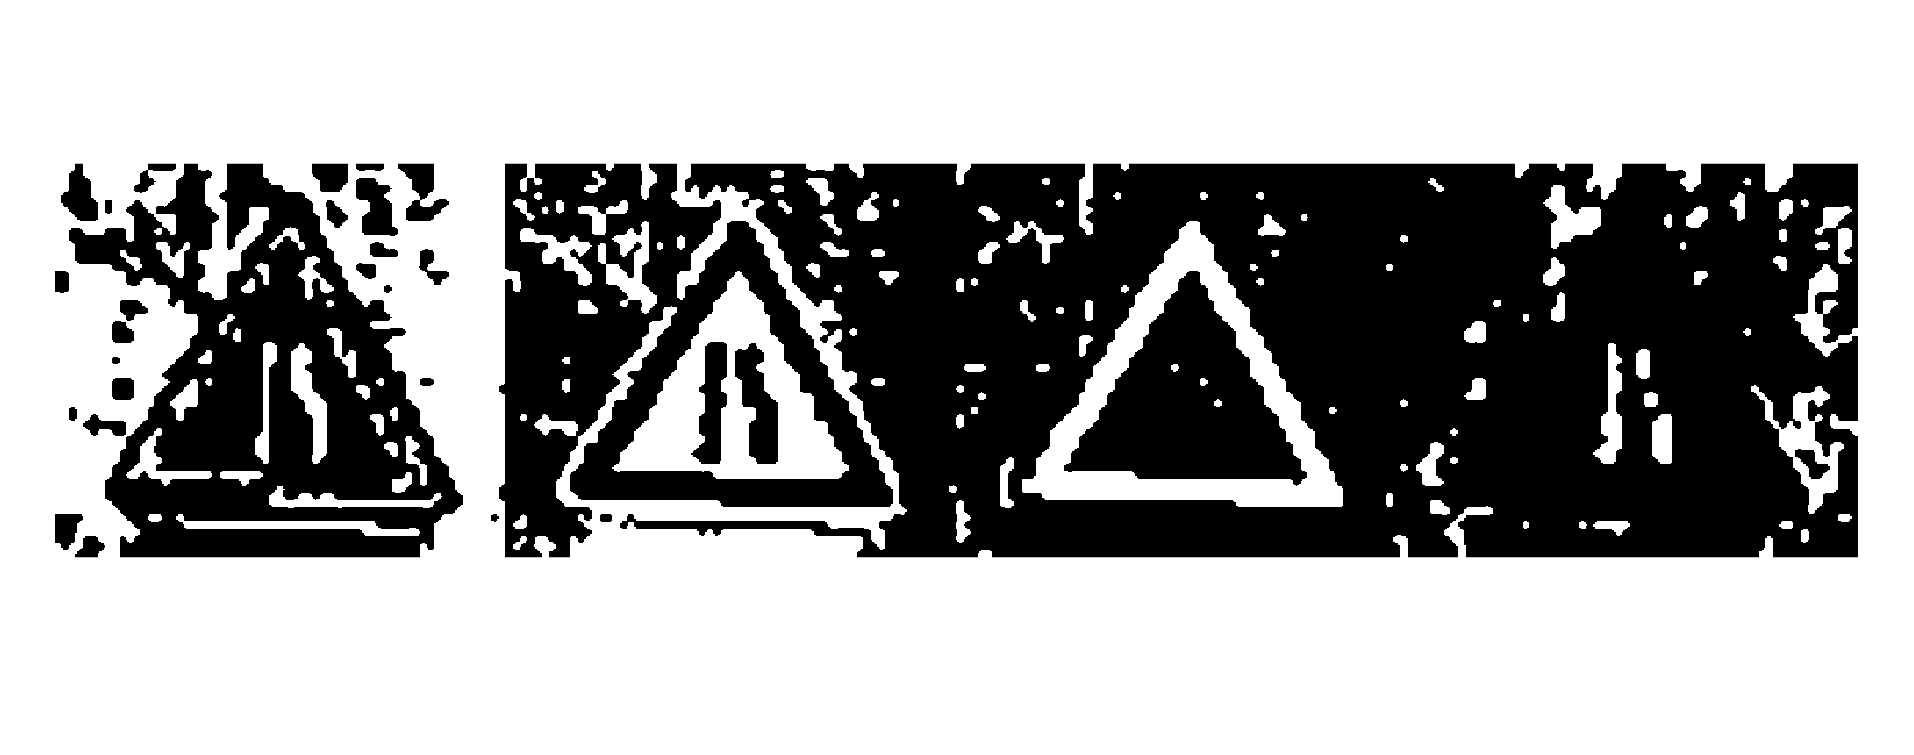

montage(struct2array(colors))%, "Size", [1, 5]);


took

took = "poly red"

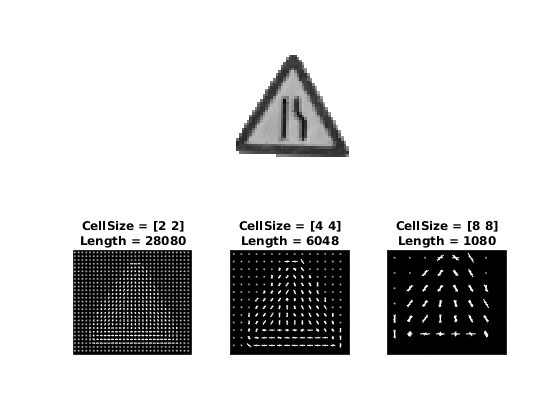


img = mask & colors.black;
G = rgb2gray(I);
G(~mask) = 256;
img = G;

% Extract HOG features and HOG visualization
[hog_2x2, vis2x2] = extractHOGFeatures(img,'CellSize',[2 2]);
[hog_4x4, vis4x4] = extractHOGFeatures(img,'CellSize',[4 4]);

[hog_8x8, vis8x8] = extractHOGFeatures(img,'CellSize',[8 8]);

% Show the original image
figure; 
subplot(2,3,1:3); imshow(img);

% Visualize the HOG features
subplot(2,3,4);  
plot(vis2x2); 
title({'CellSize = [2 2]'; ['Length = ' num2str(length(hog_2x2))]});

subplot(2,3,5);
plot(vis4x4); 
title({'CellSize = [4 4]'; ['Length = ' num2str(length(hog_4x4))]});

subplot(2,3,6);
plot(vis8x8); 
title({'CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

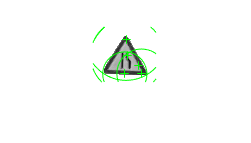


figure;
points = detectBRISKFeatures(colors.black & mask);
imshow(img);
hold on;
plot(points(end-4:end));
hold off;



C = colors.white;

imshow(C);

marker = false(size(C));
[w, h] = size(C);

marker(fix(w/2), fix(h/2)) = true;
marker(fix(w/3), fix(h/2)) = true;
marker(fix(2*w/3), fix(h/2)) = true;

FC = imfill(C, 'holes');
%E = edge(FC, 'canny');
%E = FC;

%imshow(marker)
%imshow(E)

REC = imreconstruct(marker, FC, 4);

imshow(REC)



imshow(mask);
imshow(colors.black);
bw = colors.black & mask & ~colors.red;
imshow(bw);
bw = bwareafilt(bw, 3);
imshow(bw);

G = rgb2gray(I);
masked = G.*cast(mask & ~colors.red, 'like', G);
imshow(masked)

bwm = imbinarize(masked);
imshow(bwm)

hogdata = readmatrix('train_hog.csv');


B = [0:5, 7:10, 16];
redCircle_train = hogdata(ismember(hogdata(:,end), B), :);

B = [6, 32, 41,42];
end_train = hogdata(ismember(hogdata(:,end), B), :);

B = [11, 18:31];
triangle_train = hogdata(ismember(hogdata(:,end), B), :);

B = 33:40;
blueCircle_train = hogdata(ismember(hogdata(:,end), B), :);